# Data-Driven Control Homework - SIDRA 2024 - Giorgio Ridolfi - Assignment 2 - Ex. 1

clc
close all
clear all
rng(1);
% addpath("/home/gio/Scrivania/lezioni/lezione_assignment_datadriven_sidra_2024/cvx/")
% cvx_setup



% Dimensions of system
nx = 4 ;
nu=1;
% Length of the input sequence
T = 10 ;

% Generating the input sequence u on [0,T-1] taking values in the interval
% [-1,1]^m in the form of an m x T matrix [u(0) u(1) .... u(T-1)]
magnitude=0.1;
aux=zeros(nu,T);
aux(:)=magnitude;
u(1:nu,1:T)=(2*magnitude).*rand(nu,T)-aux;
% Arranging the samples in the Hankel matrix U0 on [0,T-1]
for j=1:T-nu+1
    for i=1:nu
        U0((i-1)*nu+1:(i-1)*nu+nu,j)=u(1:nu, j+i-1);
    end
end
% If rank(U0)= m*L then the sequence u(0),...u(T-1) is PE of order L
if rank(U0) == nu*nu
    disp("input sequence is PE");
end

input sequence is PE


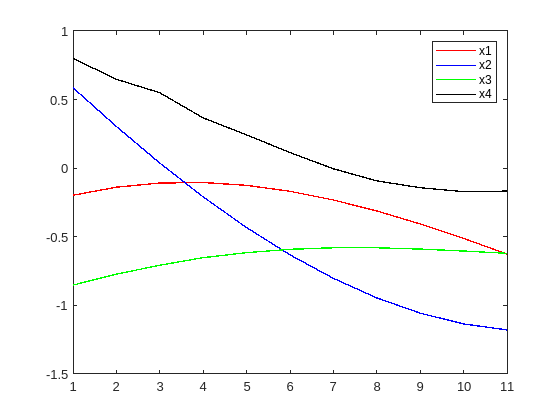

% Example 1
% Robot initial configuration and necessary data structures

x = zeros(4,T+1);
x_dot = x;
x(:,1) = randn(4,1);
x_dot(:,1) = randn(4,1);
Z0 = zeros(1,T+1);
Z0(1) = cos(x(1,1));

% System params, and matrices to write system in form x_dot = A*Z(x) + B*u
Kc = 0.4;
F2 = 0.15;
J2 = 0.2;
Nc = 2;
F1 = 0.1;
J1 = 0.15;
m = 0.4;
g = 9.8;
v = 0.1;
B = [ 0 0 0 1/J1]' ;
A = [ 0 1 0 0 0 ;
    -(Kc/J2) -(F2/J2) (Kc/(J2*Nc)) 0  -((m*g*v)/J2);
    0 0 0 1 0;
    -(Kc/(J1*Nc)) 0  (Kc/(J1*Nc)) -(F1/J1) 0 ];


deltat = 0.1 ;

for t = 1 : T
    x1 = x(1,t);
    x2 = x(2,t);
    x3 = x(3,t);
    x4 = x(4,t);
    Z_x = [ x1 x2 x3 x4 cos(x1) ]';
    Z0(t) = cos(x1);    

    % Collect state derivative
    x_dot(:,t) = A*Z_x + B*u(t);
    % Collect state
    x(:,t+1) = x(:,t) + x_dot(:,t)*deltat;
end

% Plot code taken from 
% https://github.com/zjhurug/codes-for-contraction-paper/blob/main/Ex1_one_link_robot_arm/one_link_robot_arm.m 
% and slightly modified
figure
title('Open loop')
plot(x(1,:),'r','LineWidth',1);
hold on;
plot(x(2,:),'b','LineWidth',1);
hold on;
plot(x(3,:),'g','LineWidth',1);
hold on;
plot(x(4,:),'k','LineWidth',1);
legend('x1 ','x2','x3 ','x4');


U0 = u(1:end);
X0 = x(:,1:end-1);
X1 = x_dot(:,1:end-1);
Z0 = Z0(1:end-1);
Z0 = [ X0 ; Z0 ]; 
s = size(Z0 , 1 ); % s number of nonlinear terms in Z(x)

% Sanity check, should return zeros
X1 - ( A*Z0 + B*U0 ) 

ans = 1.0e-15 *

         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.4441         0    0.2220         0         0   -0.1110         0
         0         0         0         0         0         0         0         0         0         0
   -0.2220         0   -0.4441   -0.2220    0.2220   -0.2220         0         0         0    0.0139


% RQ = [ 1 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ] ;
% 
% %% Controller design
% cvx_begin sdp
% variable P(nx,nx) symmetric
% variable Y1(T,nx)
% variable G2(T,s-nx)
% variable a
% 
% P >= 0*eye(nx);
% a >= 0;
% Z0*Y1 == [P; zeros(s-nx,nx)];
% Z0*G2 == [zeros(nx,s-nx); eye(s-nx)];
% [X1*Y1+ (X1*Y1)'+a*eye(nx) , X1*G2 , P*RQ;
%  (X1*G2)' , -eye(s-nx) , zeros(s-nx , nx);
%  (P*RQ)' , zeros(s-nx , nx) , -eye(nx)] <= 0;
% cvx_end
% G1 = Y1/P; G = [G1 G2]; K = U0*G;

% Why does this code throw a reshape error?? It's identical to the one below


RQ = [ 1 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ; 0 0 0 0 ] ;

cvx_begin sdp
variable P1(nx,nx) symmetric
variable Y1(T,nx)
variable G2(T,s-nx)
variable a
P1 >= 0*eye(nx);
a >= 0;
Z0*Y1 == [P1;zeros(s-nx,nx)];
[X1*Y1+(X1*Y1)'+a*eye(nx) X1*G2 P1*RQ;
     (X1*G2)' -eye(s-nx) zeros(s-nx,nx);
     (P1*RQ)' zeros(nx,s-nx) -eye(nx)] <= 0;
Z0*G2 == [zeros(nx,s-nx);eye(s-nx)];
cvx_end

 
Calling SDPT3 4.0: 78 variables, 58 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 58
 dim. of sdp    var  = 13,   num. of sdp  blk  =  2
 dim. of linear var  =  1
 dim. of free   var  = 22 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.6e+02|8.1e+01|8.7e+04| 5.000000e+01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.900|0.907|1.6e+01|7.6e+00|1.9e+03| 4.471479e+01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.740|0.845|4.1e+00|1.2e+00|1.5e+02| 3.325597e+01  0.000000e+00| 0:0:00

G1 = Y1/P1;
G  = [G1 G2];
K  = U0*G

K =    -6.4135   -8.2050   -9.2262   -1.1761    0.0697


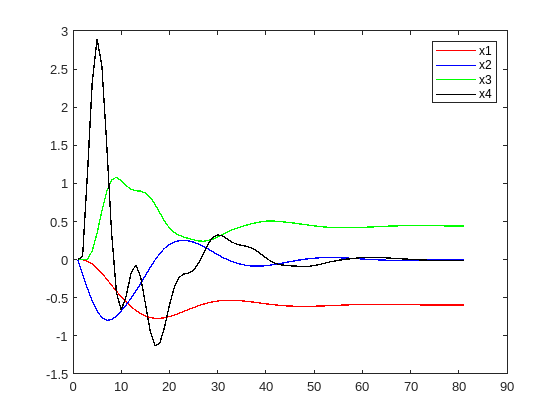


% Simulate controlled sysstem (for a longer period of time)
T = 8*T;
x = zeros(4,T+1);
x_dot = x;
x(:,1) = [0 0 0 0]';
x_dot(:,1) = randn(4,1);
Z0 = zeros(1,T+1);
Z0(1) = cos(x(1,1));

for t = 1 : T
    x1 = x(1,t);
    x2 = x(2,t);
    x3 = x(3,t);
    x4 = x(4,t);
    Z_x = [ x1 x2 x3 x4 cos(x1) ]';
    Z0(t) = cos(x1);    

    % Collect state derivative
    x_dot(:,t) = (A+B*K)*Z_x;
    % Collect state
    x(:,t+1) = x(:,t) + x_dot(:,t)*deltat;
end
figure
title('Closed loop')
plot(x(1,:),'r','LineWidth',1);
hold on;
plot(x(2,:),'b','LineWidth',1);
hold on;
plot(x(3,:),'g','LineWidth',1);
hold on;
plot(x(4,:),'k','LineWidth',1);
legend('x1 ','x2','x3 ','x4');